load('PKA_simulation_parameters_20220719.mat')
p1_PKA

p1_PKA = 0.6651

p2_PKA

p2_PKA = 0.3349


x=0:1:511;
x_time=x*12.5/256;

n512=100000*(p1_PKA*exp(-x_time/tau1_PKA)+p2_PKA*exp(-x_time/tau2_PKA));

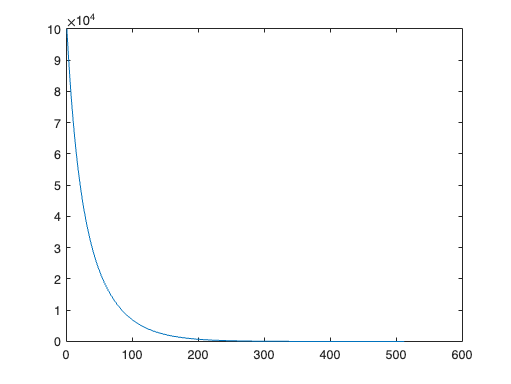

figure
plot(n512)

conv_n512=conv(n512,prf)

conv_n512 = 1.0e+04 *

         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0009    0.0035    0.0098    0.0273    0.0783    0.2107    0.4937    0.9799    1.7003    2.6182    3.6500    4.6769    5.5902    6.3084    6.8072    7.1148    7.2596    7.2816    7.2212    7.1058    6.9568    6.7886    6.6099    6.4265



length(conv_n512)

ans = 767

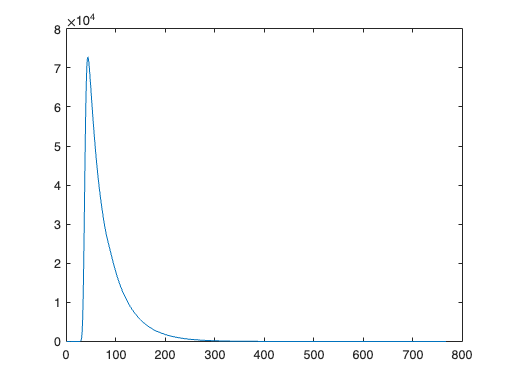

figure
plot(conv_n512)

conv_n512_1=conv_n512(257:512);
conv_n512_2=conv_n512(1:256);
conv_n512_final=conv_n512_1+conv_n512_2;

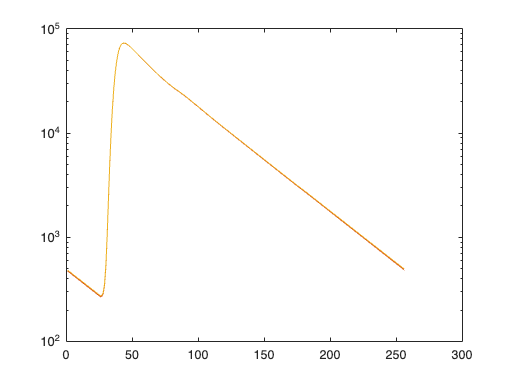

figure
semilogy(n_c_all)
hold on
semilogy(conv_n_final)
hold on
semilogy(conv_n512_final)

lft_steps=(1:1:256)*12.5/256;
weight_n_lft=lft_steps.*n_c_all;
empirical_lft_analytical=sum(weight_n_lft)/sum(n_c_all)

empirical_lft_analytical = 3.7766


weight_n_lft=lft_steps.*conv_n_final;
empirical_lft_n=sum(weight_n_lft)/sum(conv_n_final)

empirical_lft_n = 3.7766


weight_n_lft=lft_steps.*conv_n512_final;
empirical_lft_n512=sum(weight_n_lft)/sum(conv_n512_final)

empirical_lft_n512 = 3.7833


conv_n512_final_backcorr=conv_n512_final+sum(conv_n512_final)*(backcorr/samplesize_PKA);
weight_n_lft=lft_steps.*conv_n512_final_backcorr;
empirical_lft_n512_backcorr=sum(weight_n_lft)/sum(conv_n512_final_backcorr)

empirical_lft_n512_backcorr = 3.8292